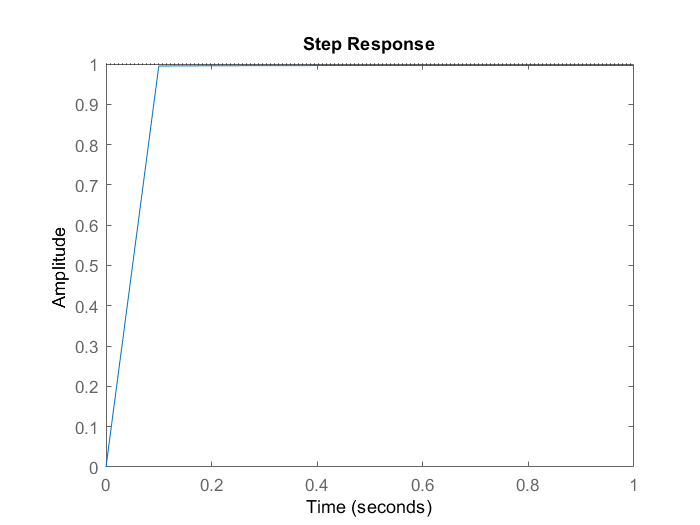

% PID tuning , bode plot diagram

J=0.01;
b=.1;
k=.1;
R=1;
L=.5;
s=tf('s');
F=k/((J*s+b)*(L*s+R)+k*k);
num=[0.1];
den=[.005 .06 .11];
[A,B,C,D]=tf2ss(num,den);
F2=ss(A,B,C,D);
kp=300;
ki=2;
kd=50;
kpid=pid(kp,ki,kd);
F3=feedback(kpid*F2,1);
t=0:0.1:1;
step(F3,t)

stepinfo(F3)

ans = struct with fields:
        RiseTime: 0.0022
    SettlingTime: 0.0042
     SettlingMin: 0.9034
     SettlingMax: 0.9941
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9941
        PeakTime: 0.0105


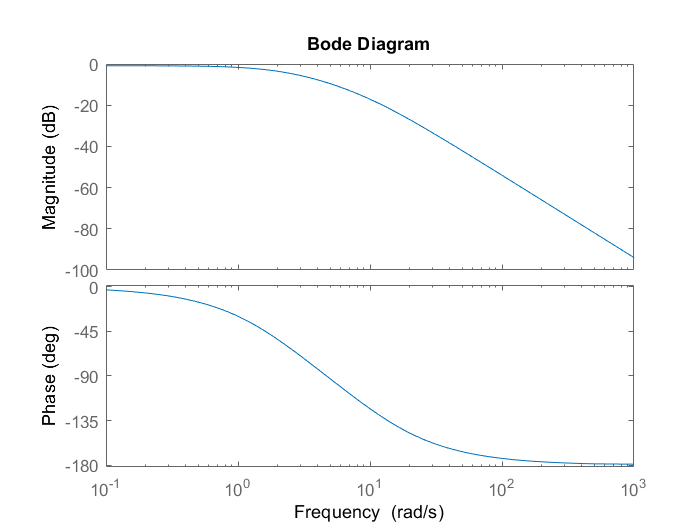


%bodeplot

bode(F)

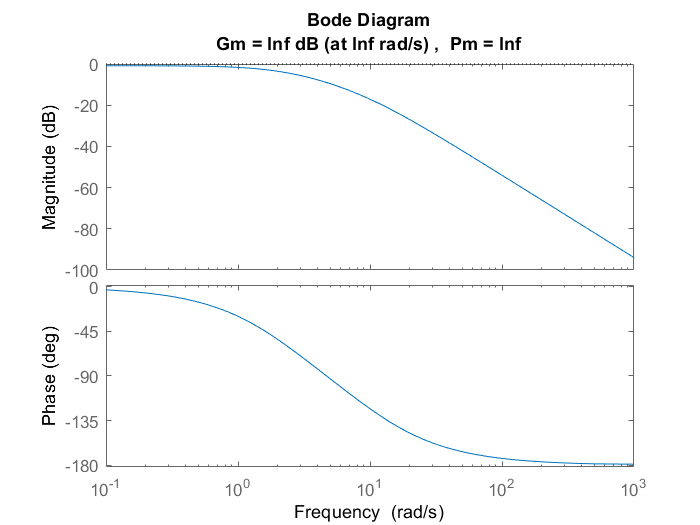

margin(F)

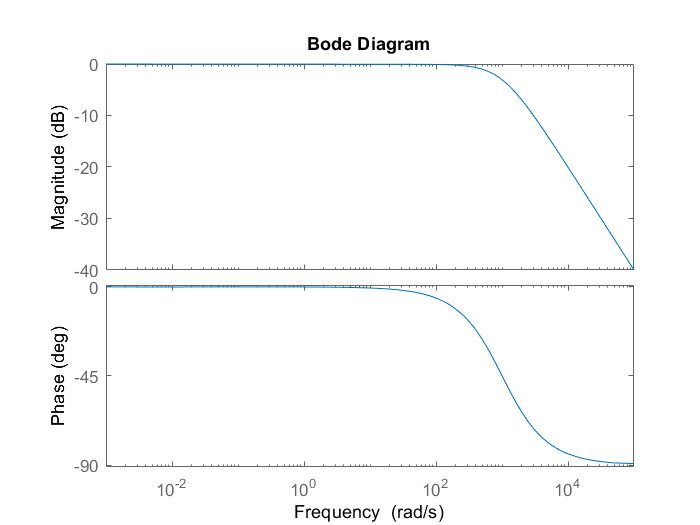


bode(F3)

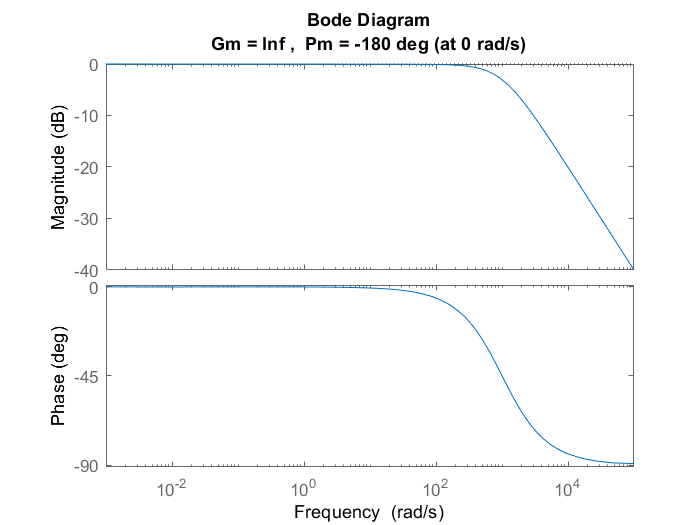

margin(F3)